A1=[-1,-4;0,-8];
A2=[-2,0;0,1];
A3=[-1,3;-3,-1];
A4=[-1,2;-5,1];
A5=[-1,1;-1,-3];
A6=[-2,0;0,-2];
A7=[1,1;1,1];
A8=[0,1;0,0];
A9=[0,0;0,0];
A10=[-4,0;0,-1];
A11=[4,0;0,1];
A=[A1;A2;A3;A4;A5;A6;A7;A8;A9;A10;A11];
tmax = 10 ;




eig_1 = eig(A1)

eig_1 =     -1
    -8


eig_2 = eig(A2)

eig_2 =     -2
     1


eig_3 = eig(A3)

eig_3 =   -1.0000 + 3.0000i
  -1.0000 - 3.0000i


eig_4 = eig(A4)

eig_4 =    0.0000 + 3.0000i
   0.0000 - 3.0000i


eig_5 = eig(A5)

eig_5 =    -2.0000
   -2.0000


eig_6 = eig(A6)

eig_6 =     -2
    -2


eig_7 = eig(A7)

eig_7 =      0
     2


eig_8 = eig(A8)

eig_8 =      0
     0


eig_9 = eig(A9)

eig_9 =      0
     0


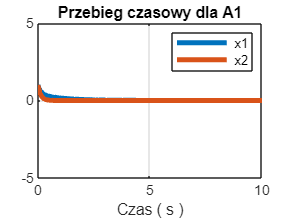

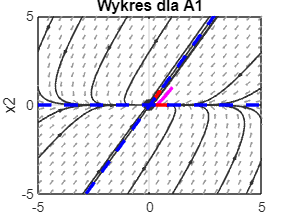

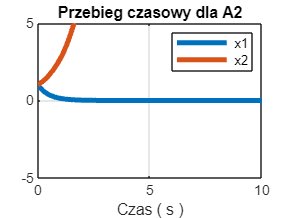

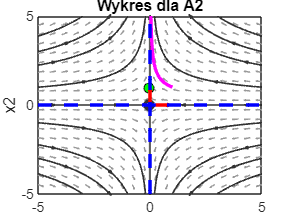

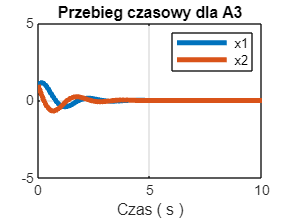

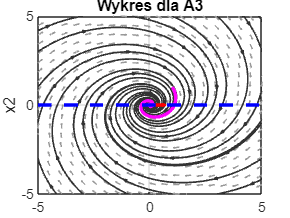

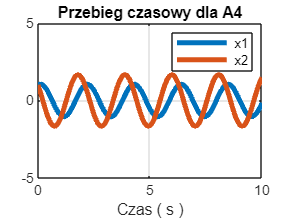

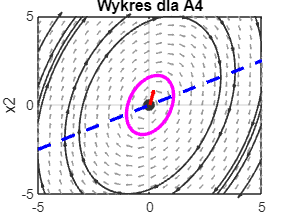

pp(A,tmax)

function pp(A,tmax)

    folder_name = 'wykresy'; % Nazwa folderu, do którego zapisywane są wykresy
    if ~exist(folder_name, 'dir')
        mkdir(folder_name); % Tworzenie folderu, jeśli nie istnieje
    end

    for i=1:11
        figure
        [ t , x ] = ode45 (@( t , x ) A((2*i-1):(2*i),:)*x , [ 0 tmax ] , [ 1 1 ]) ;
        [V,D]=eig(A((2*i-1):(2*i),:));
        scale = 10; % Skala wydłużenia wektorów własnych
        V_end1 = scale * V(:,1);
        V_end2 = scale * V(:,2);
        x_eq = null(A((2*i-1):(2*i),:) - eye(size(A((2*i-1):(2*i),:))));
        plot(t,x, 'LineWidth' ,3); grid on, hold all , xlim ( [ 0 tmax ] ) , ylim([-5 5 ] )
        legend ( ' x1 ' , ' x2 ' ,' Location ' , ' northeast ' )
        xlabel ( ' Czas ( s ) ' )
        title(sprintf('Przebieg czasowy dla A%d', i));
        %zapisywanie przebiegów czasowych
        file_name = fullfile(folder_name, sprintf('Przebieg_fazowy_A%d.png', i));
        saveas(gcf, file_name);
        hold on
        plotpp(@(t,x) A((2*i-1):(2*i),:)*[x(1);x(2)])
        plot(x(:,1),x(:,2),'m','LineWidth',2)
        scatter(x_eq(1,:), x_eq(2,:), 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'gr');
        
        quiver(0, 0, V(1,1), V(2,1), 'r','LineWidth', 2,'MaxHeadSize', 0.5); % Pierwszy wektor własny
        quiver(0, 0, V(1,2), V(2,2), 'r','LineWidth', 2,'MaxHeadSize', 0.5); % Drugi wektor własny

        if V(1,1) == 0 % Sprawdzenie, czy pierwsza składowa pierwszego wektora jest równa zero
            x_value1 = V(1,1); % Wartość x pierwszego wektora
            plot([x_value1, x_value1], [-5, 5], 'b--', 'LineWidth', 2); % Rysowanie pionowej linii
        else
            slope1 = V(2,1) / V(1,1); % Obliczenie nachylenia pierwszego wektora
            intercept1 = 0; % Przesunięcie dla pierwszego wektora przez początek układu współrzędnych
            x_values1 = linspace(-5, 5, 100); % Zakres wartości x
            y_values1 = slope1 * x_values1 + intercept1; % Obliczenie wartości y dla pierwszego wektora
            plot(x_values1, y_values1, 'b--', 'LineWidth', 2); % Narysowanie linii pierwszego wektora
        end
        
        
        % Drugi wektor
        if V(1,2) == 0 % Sprawdzenie, czy pierwsza składowa drugiego wektora jest równa zero
            x_value2 = V(1,2); % Wartość x drugiego wektora
            plot([x_value2, x_value2], [-5, 5], 'b--', 'LineWidth', 2); % Rysowanie pionowej linii
        else
            slope2 = V(2,2) / V(1,2); % Obliczenie nachylenia drugiego wektora
            intercept2 = 0; % Przesunięcie dla drugiego wektora przez początek układu współrzędnych
            x_values2 = linspace(-5, 5, 100); % Zakres wartości x
            y_values2 = slope2 * x_values2 + intercept2; % Obliczenie wartości y dla drugiego wektora
            plot(x_values2, y_values2, 'b--', 'LineWidth', 2); % Narysowanie linii drugiego wektora
        end
        title(sprintf('Wykres dla A%d', i));
        hold off
        xlabel('x1')
        ylabel('x2')
                % Zapisywanie wykresu do pliku w folderze
        file_name = fullfile(folder_name, sprintf('Wykres_A%d.png', i));
        saveas(gcf, file_name);
    end

end

